clear; close all

bigSig1 = audioread("Mic1.wav");
bigSig2 = audioread("Mic2.wav");
bigSig3 = audioread("Mic3.wav");
bigSig4 = audioread("Mic4.wav");

realizations1 = zeros(240000 , 102);
count = 1

count = 1

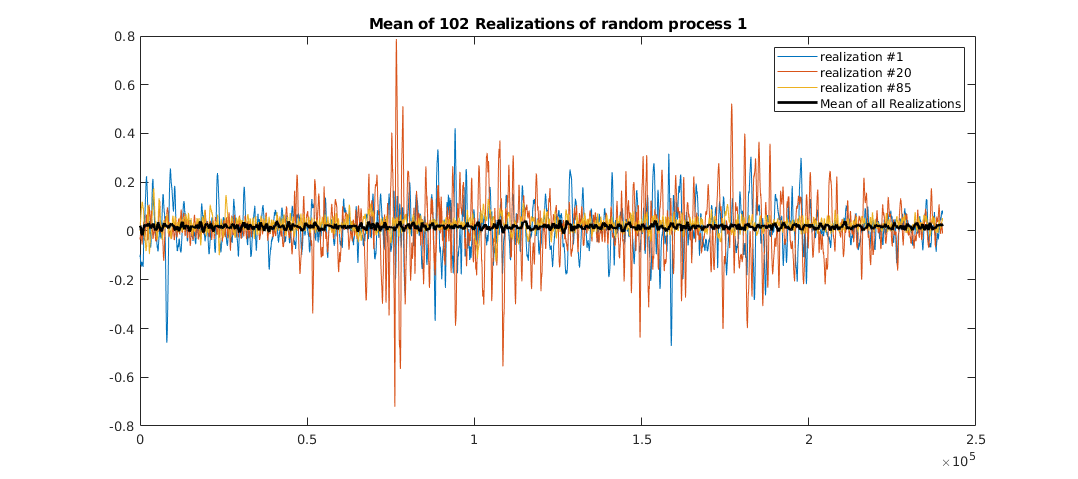


for i= 1:240000:length(bigSig1)-29320
    realizations1(:,count) = bigSig1(i:i+240000-1,1);
    count = count + 1;
end

for i= 1:240000:(length(bigSig2)-30720)
    realizations1(:,count) = bigSig2(i:i+240000-1,1);
    count = count + 1;
end

for i= 1:240000:(length(bigSig3)-28150)
    if count == 77
        break
    end
    realizations1(:,count) = bigSig3(i:i+240000-1,1);
    count = count + 1;
end

for i= 1:240000:(length(bigSig4)-28288)
    realizations1(:,count) = bigSig4(i:i+240000-1,1);
    count = count + 1;
end

mean_realizations1 = mean(realizations1, 2);
graph = figure;
plot(realizations1(:,1))
hold on
plot(realizations1(:,20))
plot(realizations1(:,85))
plot(mean_realizations1, 'k' , 'LineWidth', 2)
hold off
legend('realization #1', 'realization #20', 'realization #85', 'Mean of all Realizations')
title('Mean of 102 Realizations of random process 1')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

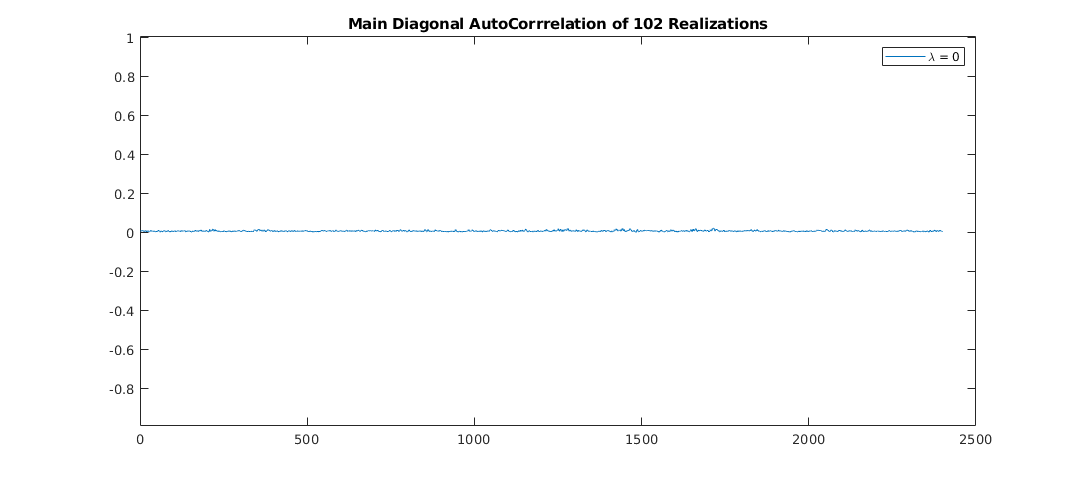

ACF = zeros(2400);

n = 1;
for l = 1 : 100 : 240000
    m = 1;
    for k = 1 : 100 :240000
        ACF(m,n) = mean(realizations1(l,:).*realizations1(k,:));
        m = m + 1;
    end
    n = n + 1;
end

D = diag(ACF);
D1 = diag(ACF, 1);
D_1 = diag(ACF, -1);
D2 = diag(ACF, 2);
D_2 = diag(ACF, -2);
D3 = diag(ACF, 3);
D_3 = diag(ACF, -3);

graph = figure;
plot(D)
ylim([mean(D)-1 mean(D)+1])
title('Main Diagonal AutoCorrrelation of 102 Realizations')
legend('\lambda = 0')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

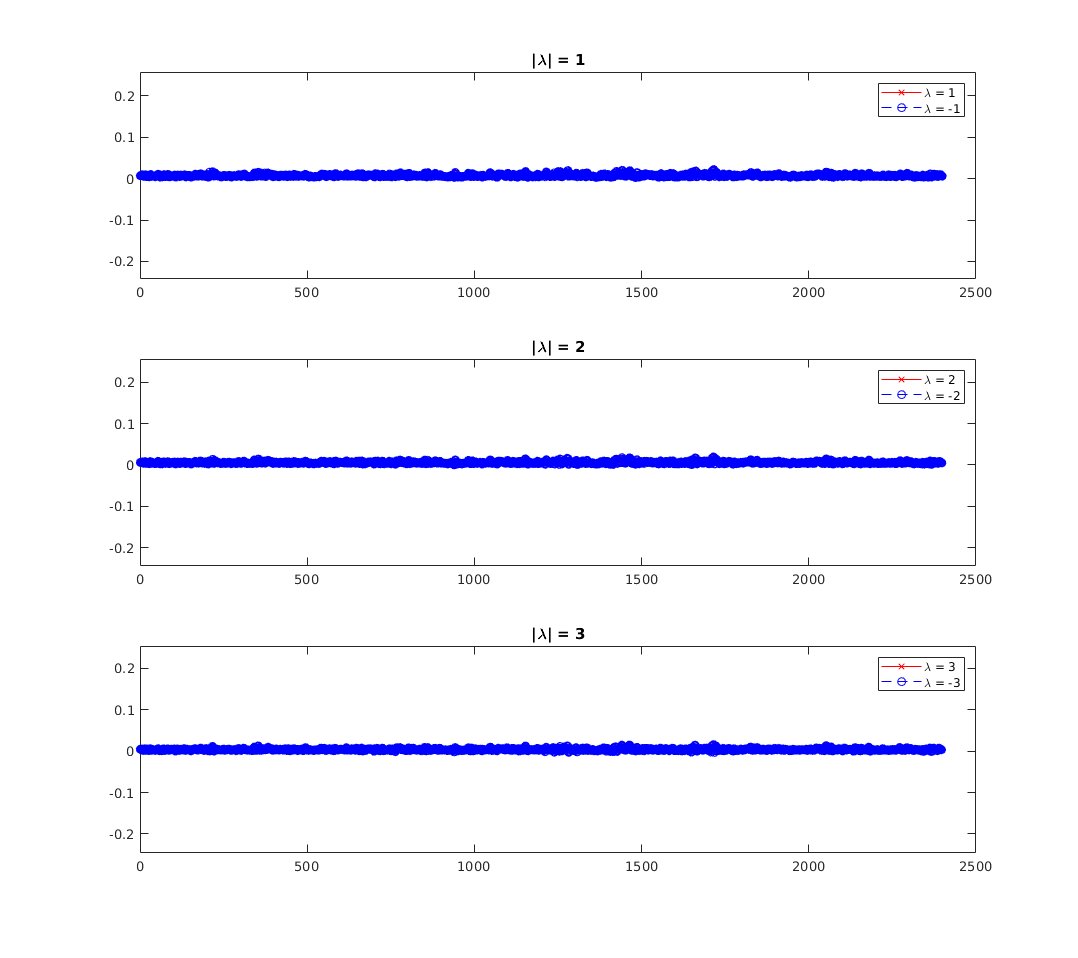

graph = figure;
subplot(3,1,1)
plot(D1,'r-x')
hold on
plot(D_1,'b--o')
ylim([mean(D1)-0.25 mean(D1)+0.25])
title('|\lambda| = 1')
legend('\lambda = 1', '\lambda = -1')

subplot(3,1,2)
plot(D2,'r-x')
hold on
plot(D_2,'b--o')
ylim([mean(D2)-0.25 mean(D2)+0.25])
title('|\lambda| = 2')
legend('\lambda = 2', '\lambda = -2')

subplot(3,1,3)
plot(D3,'r-x')
hold on
plot(D_3,'b--o')
ylim([mean(D3)-0.25 mean(D3)+0.25])
title('|\lambda| = 3')
legend('\lambda = 3', '\lambda = -3')
set(graph,'Units','normalized','Position',[0 0 1 0.5]);